Changing the current folder

cd C:\Users\washi\Documents\GitHub\thrust-analysis\post-analysis\

READING DATA FROM EXCEL

%windowSize = 32;
%b = (1/windowSize)*ones(1, windowSize);
%a = 1;
clc
clear all
t1= readtable('single_grain_simulation.xlsx')

t1 = 191×4 table
    Var1     Var2      Var3     Var4 
    ____    ______    ______    _____

       0         0         0        0
    0.03    131.82    0.0125      4.6
    0.06    133.09     0.025     5.21
    0.09    134.31    0.0375     5.78
    0.12    135.49      0.05     6.49
    0.15    136.63    0.0625     7.37
    0.18    137.72     0.075     8.29
    0.21    138.77    0.0875     9.94
    0.24    139.78       0.1    10.78
    0.27    140.74    0.1125    12.77
     0.3    141.67     0.125    15.93
    0.33    142.55    0.1375    19.11
    0.36    143.39      0.15    22.56
    0.39     144.2    0.1625    29.17
    0.42    144.96     0.175    33.12
    0.45    145.68    0.1875    98.28


t1 = table2array(t1);
actualThrust = t1(:,4)

actualThrust =          0
    4.6000
    5.2100
    5.7800
    6.4900
    7.3700
    8.2900
    9.9400
   10.7800
   12.7700


time2 = t1(:, 3)

time2 =          0
    0.0125
    0.0250
    0.0375
    0.0500
    0.0625
    0.0750
    0.0875
    0.1000
    0.1125



simthrust = t1(:, 2)

simthrust =          0
  131.8197
  133.0891
  134.3133
  135.4929
  136.6286
  137.7209
  138.7705
  139.7777
  140.7433


time1 = t1(:, 1)

time1 =          0
    0.0300
    0.0600
    0.0900
    0.1200
    0.1500
    0.1800
    0.2100
    0.2400
    0.2700


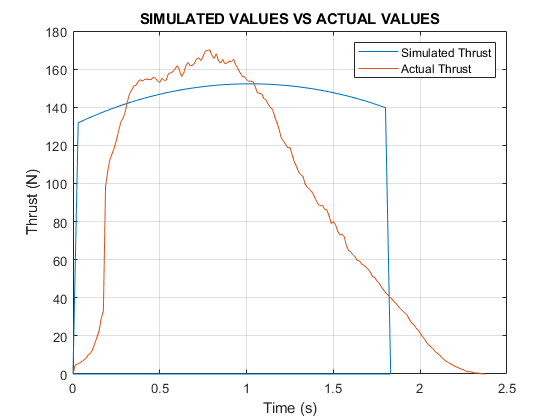


plot(time1, simthrust)
hold on
plot(time2, actualThrust)
legend('Simulated Thrust', 'Actual Thrust')
hold off

grid on
title('SIMULATED VALUES VS ACTUAL VALUES')
xlabel('Time (s)')
ylabel('Thrust (N)')


max(simthrust)

ans = 152.2869

filename = "actualthrust.csv"

filename = "actualthrust.csv"

writematrix(actualThrust, filename)

